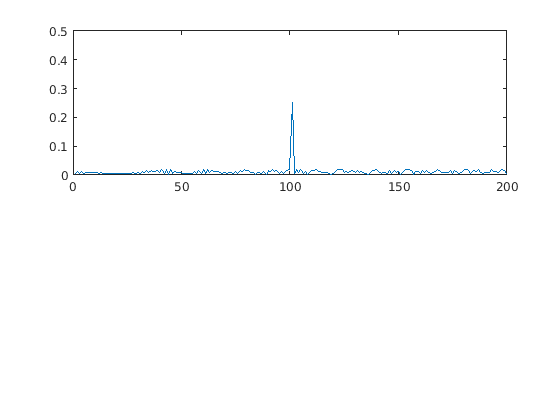

clear all
clc;

%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
%% User Defined Range and Velocity of target
% *%TODO* :
% define the target's initial position and velocity. Note : Velocity
% remains contant
target_init_range=100;
target_init_velocity=10;


%% FMCW Waveform Generation

% *%TODO* :
%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
d_res=1;
c=3e8;
R_max=200;

B=c/(2*d_res);
T_chirp=5.5*(2*R_max)/c;
slope=B/T_chirp;

%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq

                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*T_chirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
range_covered=zeros(1,length(t));
time_delay=zeros(1,length(t));


%% Signal generation and Moving Target simulation
% Running the radar scenario over the time. 

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    range_covered(i)=target_init_range+target_init_velocity*t(i);
    time_delay=2*range_covered/c;
    
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2*pi*(fc*t(i)+slope*t(i)^2/2));
    Rx(i) = cos(2*pi*(fc*(t(i)-time_delay(i)) + (slope*(t(i)-time_delay(i))^2)/2));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i).*Rx(i);
    
end

%% RANGE MEASUREMENT


 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
%Mix=reshape(Mix, [Nr, Nd]);

 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
mix_fft=fft(Mix,Nr)./Nr;


 % *%TODO* :
% Take the absolute value of FFT output
mix_fft=abs(mix_fft);

 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
mix_fft=mix_fft(1:Nr/2);

%plotting the range
figure ('Name','Range from First FFT')
subplot(2,1,1)

 % *%TODO* :
% plot FFT output 
plot(mix_fft);

axis ([0 200 0 0.5]);




%% RANGE DOPPLER RESPONSE
% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

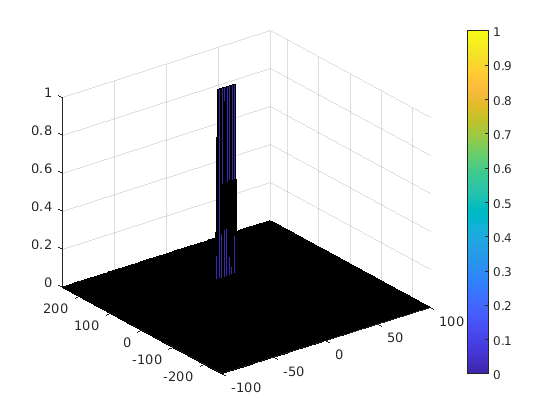

%% CFAR implementation

%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr=20;
Td=20;

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr=10;
Gd=10;

% *%TODO* :
% offset the threshold by SNR value in dB
offset=8;

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
window_size=(2*Tr+2*Gr+1)*(2*Td+2*Gd+1);
num_training_cells=window_size-(2*Gr+1)*(2*Gd+1);
signals=zeros(size(RDM));
% noise_level=zeros(1,1);

% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.
[RDM_r, RDM_d]=size(RDM);

for i=1:RDM_d-2*(Td+Gd)
    for j=1:RDM_r-2*(Tr+Gr)
        % Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
        % CFAR
        training_window=db2pow(RDM(j:j+2*(Tr+Gr),i:i+2*(Td+Gd)));
        training_window(Tr+1:Tr+2*Gr+2,Td+1:Td+2*Gd+2)=0;
        noise_level=pow2db(sum(training_window)/num_training_cells);
        threshold=noise_level*offset;
        
        % *%TODO* :
        % The process above will generate a thresholded block, which is smaller
        %than the Range Doppler Map as the CUT cannot be located at the edges of
        %matrix. Hence,few cells will not be thresholded. To keep the map size same
        % set those values to 0.
        target_d=i+Td+Gd;
        target_r=j+Tr+Gr;
        if RDM(target_r,target_d) > threshold
            signals(target_r,target_d)=1;
        end
    end
end


% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis,signals);
colorbar;